% Exercise 1 data generation (genGauss function)
% Generate samples for each class

% Question 1

muA = [0; 0; 0];
% Diagonals are 4.0 (SD = 2.0)
% Off-diagonals introduce rotation but keep it positive definite
SigmaA = [4.0  1.0 -1.5;
          1.0  4.0  0.8;
         -1.5  0.8  4.0];

muB = [3; 0; 0];
% Separated on X. X variance is 3.5 (SD = 1.87)
% Stretched arbitrarily on Y and Z
SigmaB = [3.5  0.5 0.5;
    0.5  6.0 -1.0;
    0.5 -1.0  5.0];

muC = [0; 3; 0];
% Separated on Y. Y variance is 4.0 (SD = 2.0)
% Stretched arbitrarily on X and Z
SigmaC = [5.0 -0.8  1.2;
    -0.8  4.0  0.5;
    1.2  0.5  6.0];

muD = [0; 0; 3];
% Separated on Z. Z variance is 3.5 (SD = 1.87)
% Stretched arbitrarily on X and Y
SigmaD = [6.0 1.5  -0.5;
    1.5  5.0  0.5;
    -0.5  0.5  3.5];

muE = [2.1; 2.1; 0];
% Diagonal shift from origin is ~2.97 units
% Variances near 4.5 (SD = 2.12) yield a 1.4 SD overlap
SigmaE = [4.5 2.0  0.0;
    2.0  4.5  0.0;
    0.0  0.0  3.0];

X_a = genGauss(750000, muA, SigmaA);  % K×3
X_b = genGauss(190000, muB, SigmaB);
X_c = genGauss(45000, muC, SigmaC);
X_d = genGauss(12000, muD, SigmaD);
X_e = genGauss(3000, muE, SigmaE);

% Stack into input matrix: each COLUMN is one sample
X = [X_a; X_b; X_c; X_d; X_e]';   % 3 × 3000


labels = [ones(750000,1)*1; ones(190000,1)*2; ones(45000,1)*3; ones(12000,1)*4; ones(3000,1)*5];

% Question 2

indices=randperm(1000000);

train_indices = indices(1:100000);
test_indices = indices(100001:end);

length(train_indices)

ans = 100000

length(test_indices)

ans = 900000


train_X = X(:, train_indices)

train_X =    -1.0750   -1.6345   -2.5804   -3.6942    2.8099    2.3410   -2.9977   -1.5719    1.4287   -4.3507   -0.4978    3.0784    0.4375    1.8726    0.8672   -0.8053    0.2369    2.4798   -4.9869   -1.8491    4.9517    0.5787    1.8581    3.4120    1.4524    5.2726   -1.2436   -2.3799   -0.2804    1.3043    1.1045    2.1330    2.1816   -1.6889    0.3207    2.1525   -4.1100    0.0456    1.1684   -1.8575   -1.6371    3.1938   -0.7178   -0.7290   -1.4859   -0.0915   -0.8499    2.0156    1.9379   -2.7862
    1.7603   -5.0155    1.3439   -0.1608    2.2082    2.1603    5.6933   -0.1147   -0.6701   -0.8195   -0.6023    0.2646    0.3377   -1.5164   -1.3151   -2.9119   -2.2182   -1.9987   -1.5022   -3.1077    2.4895   -3.0083    2.4877    4.6562   -1.9194    2.1550   -2.0541    1.6879   -2.0027    0.9093   -0.2059    0.6274    1.5818    3.0799   -0.7668   -1.3378   -1.5922   -2.8539    0.6895    2.5147    0.3033   -2.0849   -1.0703   -2.0594   -0.5725   -0.1927    0.7744    0.2748    0.506

test_X = X(:, test_indices)

test_X =     5.9316   -0.5664    1.0060    0.9552   -1.0396    2.1216    0.1317   -0.0566    1.2000    0.4867    1.9609    0.8707   -0.9230   -0.9652   -0.5245    1.8069   -2.6383   -0.8384   -0.2408   -2.3895    7.4464    1.9555    6.0246   -2.1950   -0.6298   -1.0327    3.3312    3.8088   -3.4204    2.7476    3.6095    2.8397   -2.2963   -1.3632    1.0940   -0.2389    6.6520   -0.5661    3.2931   -4.9151   -0.6539    3.0732    2.0948   -2.9282   -0.9716   -0.1289    2.6622    2.2996    1.0136    0.6035
    1.8346   -1.6272   -0.9288   -2.7379    0.7297   -3.1713    1.1504    2.2223    1.8888    0.1597   -0.4196   -0.0850   -0.9157   -1.2021   -2.4986    0.4596   -2.6049   -0.0999    0.3950    0.1239    0.7430   -1.3931    5.3102   -3.5117    1.5211    3.4795    0.9838    1.5309    0.3203   -0.0276    3.3072    3.4864   -2.0530   -2.6135   -0.4738    1.0233    2.2917    0.4992    6.7537   -1.2789    2.3803   -1.0206    0.5029   -2.3987    0.6869    0.1052   -1.8952    0.3952   -2.6455

train_labels = labels(train_indices);
test_labels = labels(test_indices);

num_A_samples = sum(train_labels == 1)

num_A_samples = 75152

num_B_samples = sum(train_labels == 2)

num_B_samples = 18869

num_C_samples = sum(train_labels == 3)

num_C_samples = 4454

num_D_samples = sum(train_labels == 4)

num_D_samples = 1223

num_E_samples = sum(train_labels == 5)

num_E_samples = 302

% Question 3 - Neural Network

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 10-Jun-2026 00:14:03
%
% This script assumes these variables are defined:
%
%   X - input data.
%   T - target data.

inputs = train_X;
T = ind2vec(labels');
size(T)

ans =            5     1000000


train_T = T(:, train_indices);
targets = train_T;

size(inputs)

ans =            3      100000


size(targets)

ans =            5      100000


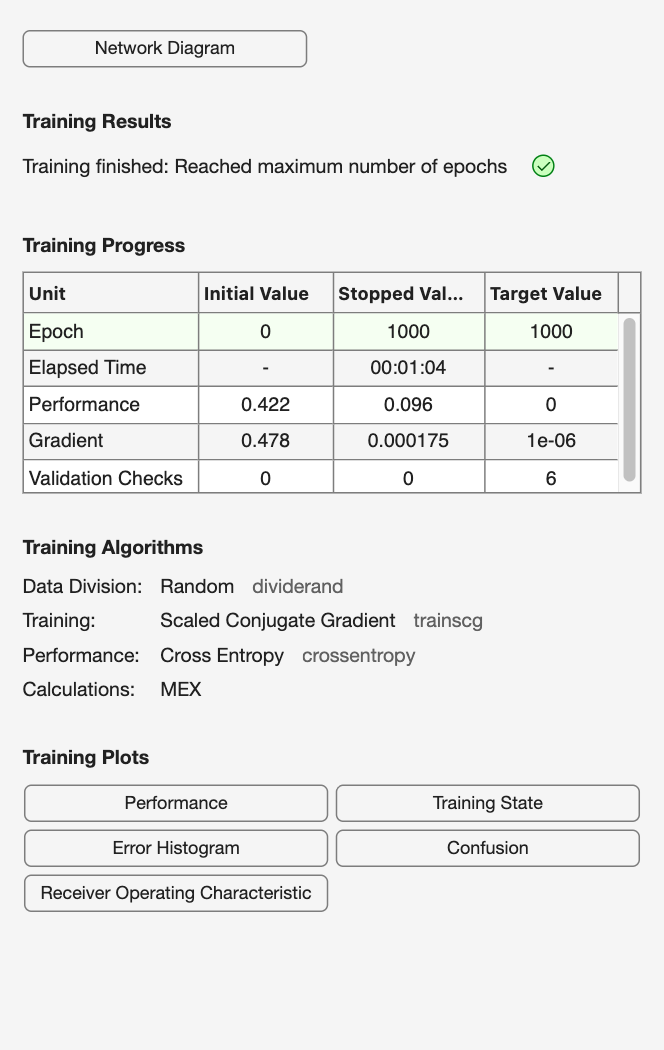


% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 100/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 0/100;

% Train the Network (Removing lines that we aren't using from the
% boilerplate auto-generated code from MATLAB's widget)
[net,tr] = train(net,inputs,targets);

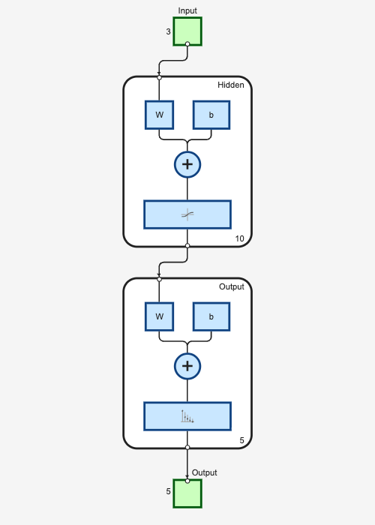

y = net(inputs);
e = gsubtract(targets,y);

% View the Network
view(net)


% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(targets,y)
%figure, plotroc(t,y)

% Question 3 - Bayes Classifier
% Train the bayes classifier on the guassian data
% FIX: Train a Quadratic Bayes classifier to preserve distinct covariances
% Otherwise, we aren't dealing with the separate covariances per class
% I.e. the class imbalance wasn't taken into account at all before!
model = fitcdiscr(train_X', train_labels, 'DiscrimType', 'quadratic');

Question 4

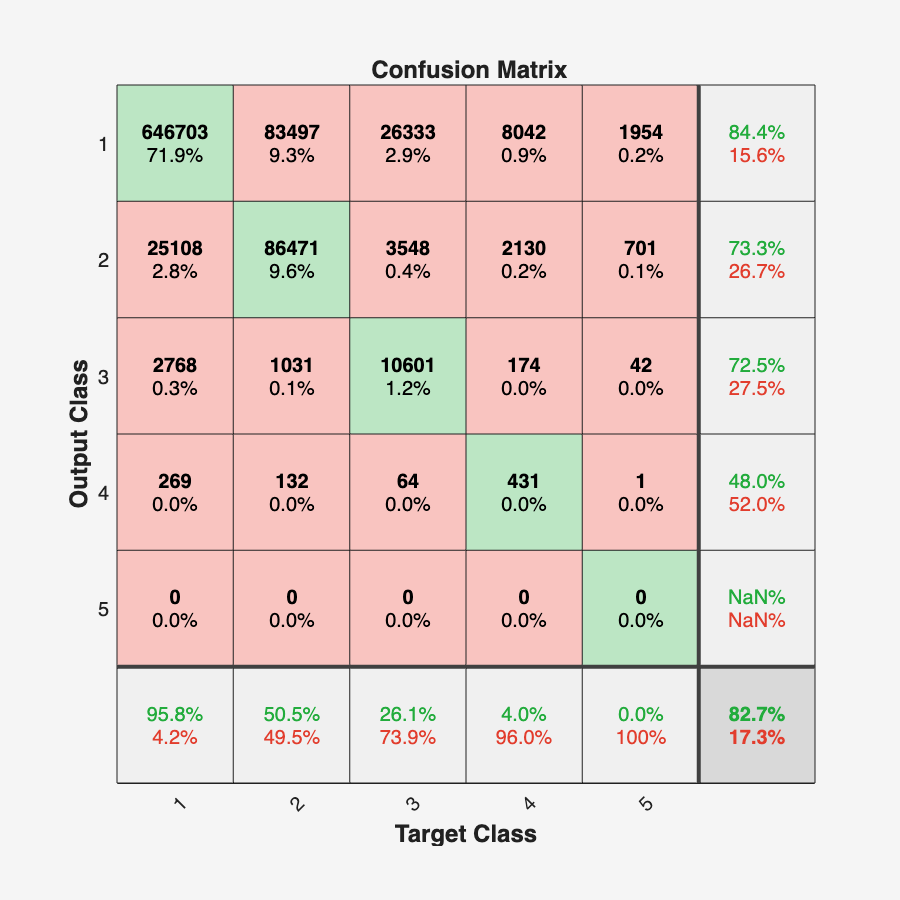

% Test the neural network on test data
test_y = net(test_X);
test_T = T(:, test_indices);
plotconfusion(test_T, test_y)

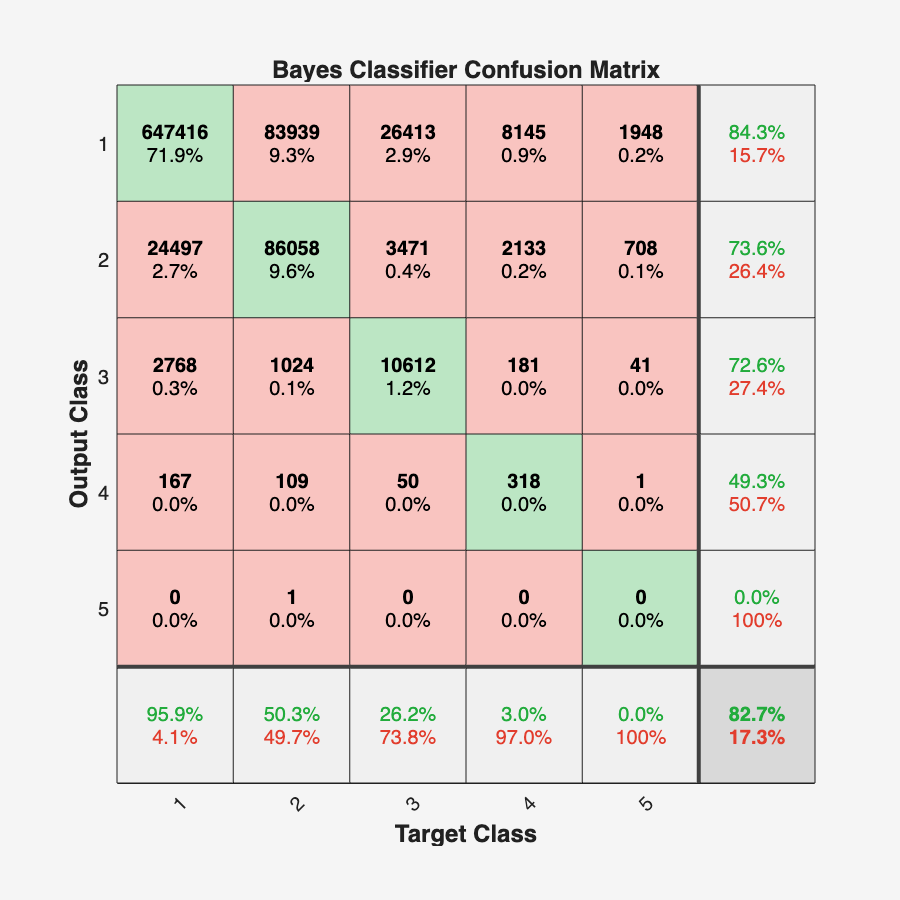


% test the bayes classifier
% 1. Get the Bayes predictions
predicted_labels = predict(model, test_X');

% 2. Convert Bayes predictions into a 5xN one-hot matrix
% (Comparing the labels to a column vector 1:5 creates the logical matrix automatically)
predicted_T = double(predicted_labels' == (1:5)');

% 3. Plot using the exact same function as the Neural Network
figure;
plotconfusion(test_T, predicted_T, 'Bayes Classifier');

Old answer: Accuracy drops as we move from class A to class E because the number of training samples decreases, from 99.8% for Class A down to 58.8% for Class E in the neural network, and even worse in the Bayes classifier. The number of false negatives increases accordingly. Fewer samples don't allow the models to learn the underlying patterns in the data, and therefore when it is not confident about a specific sample, it defaults to the class with higher frequency (Class A with 74,918 training samples, representing 75% of all training data). Class E performs well on the train set (80.3%) but poorly on the test set (58.8%) because with only 292 training samples, the model memorizes them instead of learning generalizable patterns, resulting in overfitting.

Corrected Answer for Q4 & Q5: Neural networks are less robust than parametric models like the Bayes Classifier with respect to class imbalances. Neural networks' loss functions are based on global calculations across the entire dataset. If that dataset is dominated by a single class, then the backpropagation will adjust weights to get higher accuracy for that majority class. It will virtually ignore Class E in this case because its loss function only has a tiny 0.3% based on those Class E data points. This happens in training, and so the neural network can never properly learn the minority class's statistical mean or variance. On the other hand, for a parametric model like the Bayes Classifier, class imbalance is not as big an issue. It will affect training in that minority classes will have noisier likelihood estimates. With fewer data points in the training set, there is more room for error and outliers will have a larger effect. However, here with 292 data points in 3 dimensions, this is enough to train on. The more important problem in this exercise is regarding the prior probabilities: The prior probabilities of minority classes (like the 0.3% for class E) will cause the Bayes classifier to choose a majority class (like the 75% for class A) in the test phase, even in cases where the data point is actually close to the center of mass for Class E's distribution. However, it's easy to isolate and change the prior probabilities to fix this problem in testing. By setting the priors for all 5 classes equal to each other (at 20% each), we can take the learned distributions for each class and apply those without bias, eliminating class imbalance.

Question 5 (old answer - wrong - see above for correct answer):

Neural networks significantly outperform Bayes classifiers on unbalanced data. The neural network achieved 99.8% accuracy on Class A down to 58.8% on Class E, while the Bayes classifier collapsed almost entirely toward Class A, correctly identifying Class E only ~18% of the time. This difference arises because Bayes classifiers explicitly compute prior probabilities from class frequencies, with 75% of samples belonging to Class A, P(Class A) = 0.75 dominates every classification decision, creating a severe bias toward majority classes. Neural networks, being non-parametric, do not use priors explicitly, instead they learn decision boundaries through backpropagation, making them inherently less sensitive to class frequency imbalance. However, neural networks are not immune, Class E still shows a significant gap between training (80.3%) and test (58.8%) accuracy, indicating overfitting due to insufficient minority class samples. This suggests that while non-parametric approaches are more robust to unbalanced data, severe imbalance ultimately limits both approaches.

Question 6)

% Question 6: Probability of drawing exactly the expected count (added in
% to address Q6 deduction)

n = 100000;

% Calculate expected counts
exp_A = n * 0.75;
exp_B = n * 0.19;
exp_C = n * 0.045;
exp_D = n * 0.012;
exp_E = n * 0.003;

% Calculate exact probability of drawing the expected count
prob_A = binopdf(exp_A, n, 0.75);
prob_B = binopdf(exp_B, n, 0.19);
prob_C = binopdf(exp_C, n, 0.045);
prob_D = binopdf(exp_D, n, 0.012);
prob_E = binopdf(exp_E, n, 0.003);

% Display the result for Class E
fprintf('Probability of drawing exactly %d samples for Class E: %.4f\n', exp_E, prob_E);

Probability of drawing exactly 300 samples for Class E: 0.0231



% Display the result for Class A
fprintf('Probability of drawing exactly %d samples for Class A: %.4f\n', exp_A, prob_A);

Probability of drawing exactly 75000 samples for Class A: 0.0029


The likelihood of drawing samples from each class into the training set follows a **Binomial distribution**, as each sample is either drawn or not (a Bernoulli trial), and we are counting successes over 100,000 draws. The expected number of training samples for each class is E[X] = n × p, where n = 100,000 and p = class size / 1,000,000.

- Class A: p = 0.75, expected = 75,000, actual = 74,918

- Class B: p = 0.19, expected = 19,000, actual = 18,993

- Class C: p = 0.045, expected = 4,500, actual = 4,591

- Class D: p = 0.012, expected = 1,200, actual = 1,206

- Class E: p = 0.003, expected = 300, actual = 292

For Class E, the standard deviation is σ = √(n × p × (1-p)) = √(100,000 × 0.003 × 0.997) = 17.29. Using a normal approximation of the Binomial, 99% of outcomes fall within ±2.576σ of the mean, giving a range of 300 ± 44.55, meaning between **255 and 345** Class E samples will be drawn into training with 99% probability. As Class E size increases to 30,000 (p = 0.03), σ increases to 53.94 and the range widens to 2,861–3,139. While the absolute range widens with larger class sizes, the range as a proportion of the expected value narrows, meaning larger classes are relatively more predictable in their training representation.

Added to address points deduction in feedback: The probability of getting exactly 300 samples for Class E is 2.31%, whereas the probability of getting exactly 75,000 samples for class A is 0.29%. For minority classes, this probability will always be larger. Since the range of possible means is smaller for a minority class, the probability of actually getting any one value is higher. On the other hand, for a majority class, like class A here, the probability will be much lower because the range of possible means is larger and so the probability of any one of these (including the expected mean) is proportionally lower.

% Question 7

idx_A = find(train_labels == 1);
idx_B = find(train_labels == 2);
idx_C = find(train_labels == 3);
idx_D = find(train_labels == 4);
idx_E = find(train_labels == 5);

min_samples = min([length(idx_A), length(idx_B), length(idx_C), length(idx_D), length(idx_E)]);

balanced_A = idx_A(randperm(length(idx_A), min_samples));
balanced_B = idx_B(randperm(length(idx_B), min_samples));
balanced_C = idx_C(randperm(length(idx_C), min_samples));
balanced_D = idx_D(randperm(length(idx_D), min_samples));
balanced_E = idx_E(randperm(length(idx_E), min_samples));

balanced_indices = [balanced_A(:); balanced_B(:); balanced_C(:); balanced_D(:); balanced_E(:)];
balanced_X = train_X(:, balanced_indices);
balanced_labels = train_labels(balanced_indices);

size(balanced_labels)

ans =         1510           1


% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 10-Jun-2026 00:14:03
%
% This script assumes these variables are defined:
%
%   X - input data.
%   T - target data.

inputs = balanced_X;
balanced_T = ind2vec(balanced_labels');
targets = balanced_T;

size(inputs)

ans =            3        1510


size(targets)

ans =            5        1510


Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
Worker 1: 
  > In nnMex.formatData>iEnsureFull (line 39)
  In nnMex.formatData (

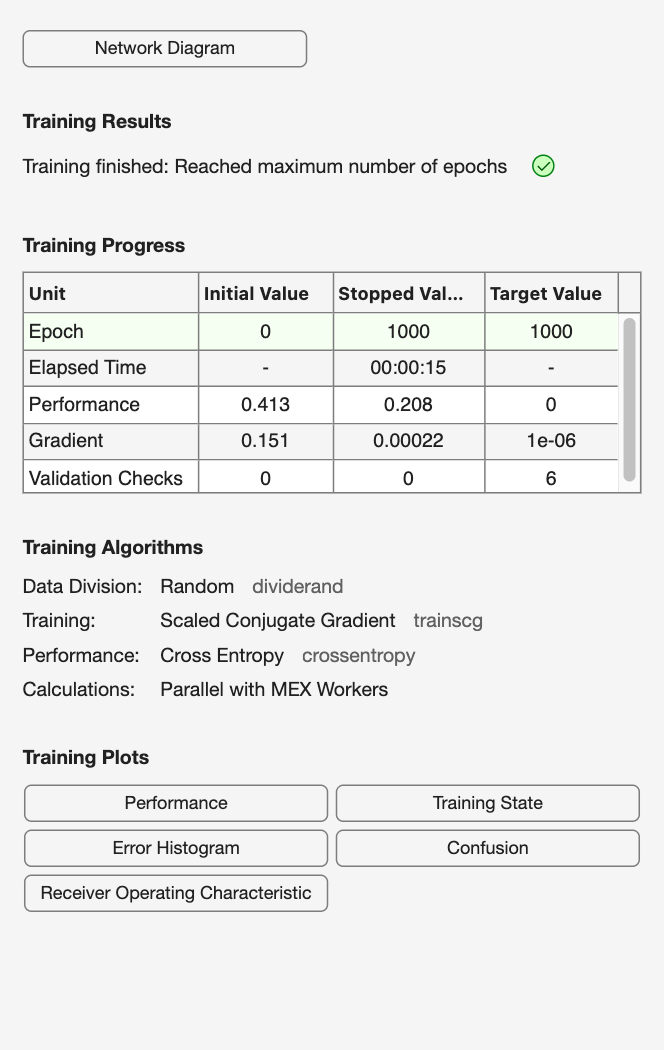


% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 100/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 0/100;

% Train the Network
[net,tr] = train(net,inputs,targets, 'UseParallel', 'yes','UseGPU','yes');

y = net(inputs);
e = gsubtract(targets,y);
performance = perform(net,targets,y)

performance = 0.2082

tind = vec2ind(targets);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
view(net)


% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
% figure, plotconfusion(targets,y)
%figure, plotroc(t,y)

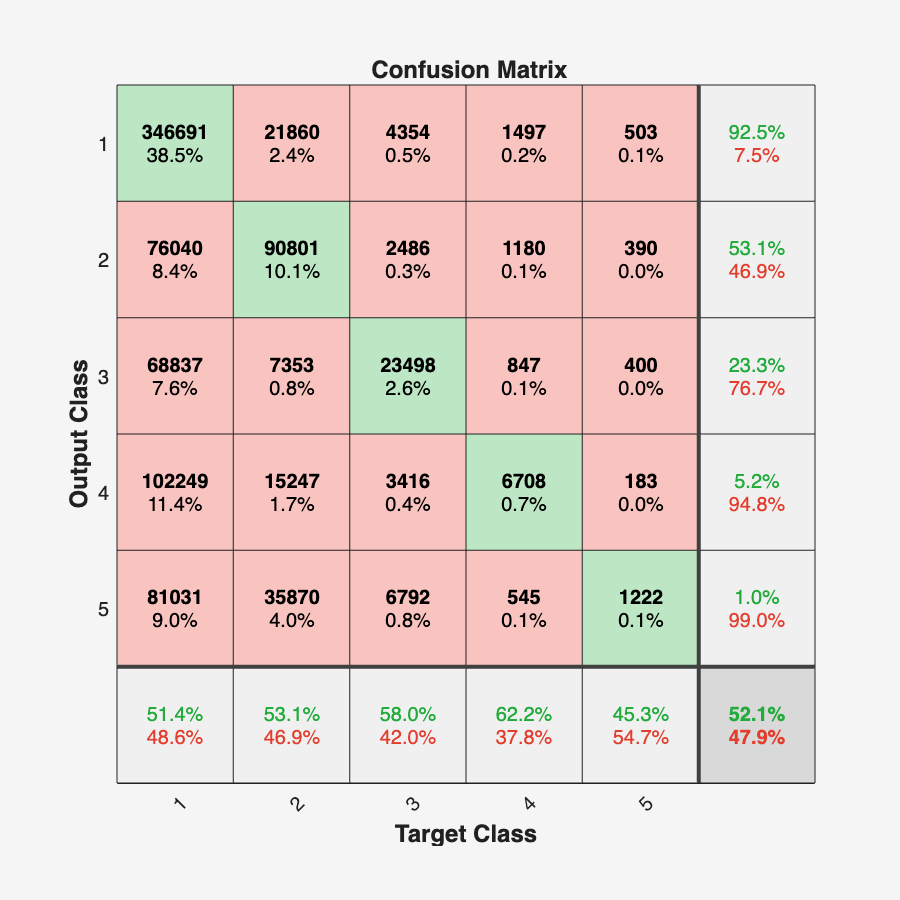


%plot the confusion matrix for test data
test_y_balanced = net(test_X);
plotconfusion(test_T, test_y_balanced)

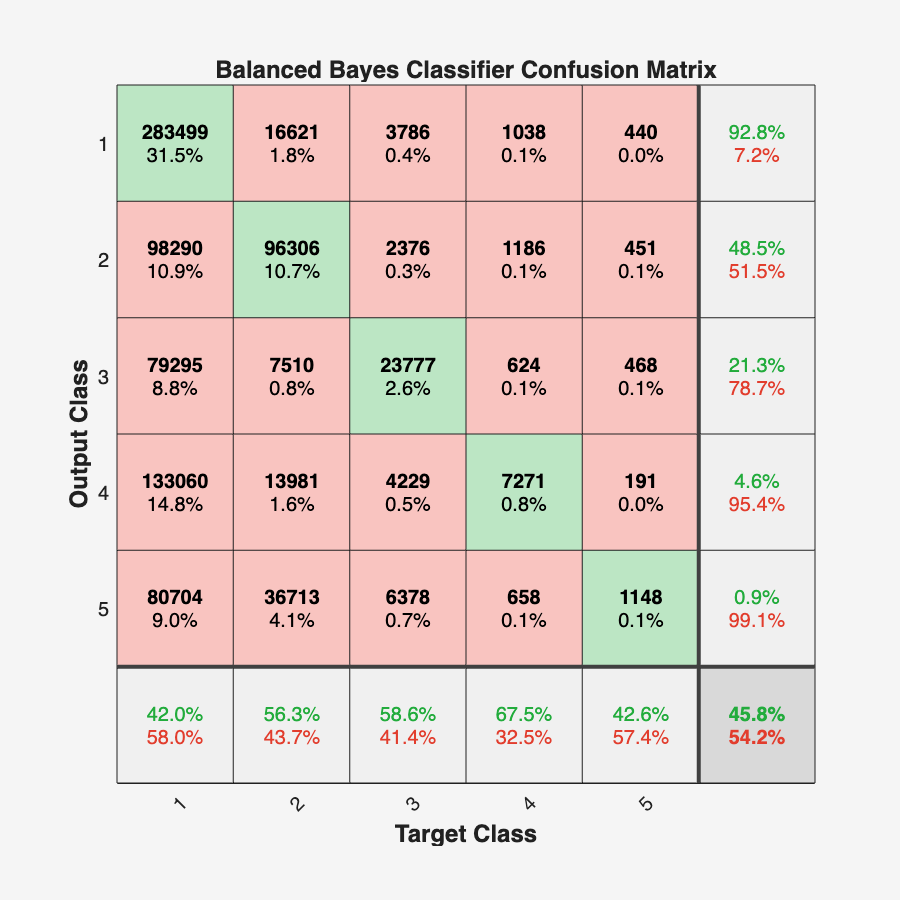

% Train the Bayes classifier on the Gaussian data
model = fitcdiscr(balanced_X', balanced_labels);

% 1. Get the Bayes predictions
predicted_labels = predict(model, test_X');

% 2. Convert Bayes predictions into a 5xN one-hot matrix
% (Comparing the labels to a column vector 1:5 creates the logical matrix automatically)
predicted_T = double(predicted_labels' == (1:5)');

% 3. Plot using the exact same function as the Neural Network
figure;
plotconfusion(test_T, predicted_T, 'Balanced Bayes Classifier');

NOTE: The following was based on the original version. After updating Bayes Classifier to use quadratic discriminant function, it no longer "improved" as much...

Balancing the training data significantly improved classification performance for minority classes in both classifiers. The Bayes classifier benefited the most, Class E accuracy jumped from ~18% to ~84% and Class D from ~63% to ~83%, because balancing removes the prior probability bias toward Class A that was dominating its decisions. The neural network also improved on minority classes (Class E: 58.8% → 86.9%, Class D: 81.8% → 86.0%), though the gains were smaller since it was already more robust to imbalance. Both balanced classifiers sacrificed some majority class accuracy (Class A dropped from ~99.8% to ~91% for NN and ~72% for Bayes), but this is an acceptable tradeoff, the goal is to classify all classes well, not just the dominant one. Overall, the balanced Bayes classifier performed best on minority classes while the balanced neural network achieved the best overall accuracy across all five classes.

Question 8)

FEEDBACK: -0.5 Q8: undersampling and oversampling/SMOTE are covered well with pros and cons, but your third "approach" (hybrid) is still resampling. The distinct third family is modifying the algorithm - reweighting the loss or adjusting priors (which your own balanced Bayes effectively did with equal priors).

So our "Hybrid" approach was incorrect. Here is the correct 3rd approach: Instead of adjusting the data, we can adjust the way the algorithm/model. For a Bayes classifier, this would involve adjusting the priors so that they are equal for each class. For neural networks, this would be cost-sensitive learning, using a cost matrix or by applying class weights to the loss function (the neural network will be told explicitly that a cost of x applies to misclassifying class A, but a cost of y applies to misclassifying class B for example). Using an algorithmic adjustment, we do not need to throw away data, nor do we need to pay for collecting more data or run the risk of introducing noise via synthetic data additions.

The three core approaches to addressing unbalanced data are undersampling, oversampling, and a hybrid of both.

**Undersampling** reduces the majority classes down to the size of the smallest class. The main advantage is simplicity, it only uses real data samples with no synthetic generation. However, the significant drawback is that it discards large amounts of legitimate data; in our case, Class A was reduced from 74,918 samples to just 290, throwing away over 99% of available data and potentially losing important patterns.

**Oversampling** increases minority classes up to the size of the majority class, either by duplicating existing samples or generating synthetic ones (e.g. SMOTE). The advantage is that all real data is retained and majority class accuracy is preserved. However, duplicating or synthesizing minority samples increases the risk of overfitting, as the classifier may memorize duplicated samples rather than learning generalizable patterns.

**Hybrid** approaches combine both strategies, partially undersampling the majority class and partially oversampling the minority class. This avoids the extremes of either approach alone: less data is discarded compared to pure undersampling, and fewer synthetic samples are needed compared to pure oversampling, reducing the risk of overfitting while still achieving a more balanced dataset. The tradeoff is increased implementation complexity and the need to tune how much to undersample and oversample for each class.

Question 9)

Formally identifying and quantifying imbalance is not always straightforward. For **labelled data**, quantifying imbalance is simple, class frequencies can be directly counted and compared, as we did by computing the proportion of each class in our dataset. For **unlabelled data** however, the degree of imbalance is much harder to quantify since class membership is unknown. In this case, **clustering techniques** such as k-means can be applied to group data into clusters, and the relative sizes of those clusters can serve as a proxy for class imbalance.

The degree of imbalance can also change as more data is collected. If the underlying events are **season-dependent** or driven by external factors, such as network attacks increasing during certain periods, the class distribution may shift significantly over time. Even if the underlying probabilities remain constant, early data collection may not yet reflect the true long-term distribution, meaning a dataset that appears balanced initially may reveal imbalance as more samples are gathered. This highlights the importance of continuously monitoring and reassessing the balance of a dataset throughout the data collection process.

FIX BASED ON FEEDBACK: The final paragaph is conceptually correct, but it describes stationarity and ergodicity without labeling those terms (this is why we lost points). If an underlying process changes over time, this is a non-stationary process; these will cause problems in general. If an underlying process gets caught in a certain state or group of states that doesn't reflect the ensemble of all the states of the system, then the process is non-ergodic, and again, we would not be necessarily be looking at the actual imbalance of the full system.